%% il est question ici de réprésenter la propagation de la température de la pelouse d'un stade de football
%% Pour celà, nous détermineront la valeur de la température en chaque point à partir d'une déduction grace au Laplacien
%% Notre système sera modélisé sous la forme: P*A=T avec P les coefficients du système d'équation; A l'ensemble des inconnnues que nous détermineront, T étant la somme de la fonction F(fonction de x et y) et de la valeur de la température en un point du contour.

%% Détermination de P
n=35;
M = toeplitz([-4 0 0 0 0 1 zeros(1,n-6)],[-4 0 0 0 0 1 zeros(1,n-6)] );
M(6,2)=1;
H = toeplitz([0 1 zeros(1,n-2)],[-4 1 zeros(1,n-2)] );

P=M+H

P =     -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -4     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

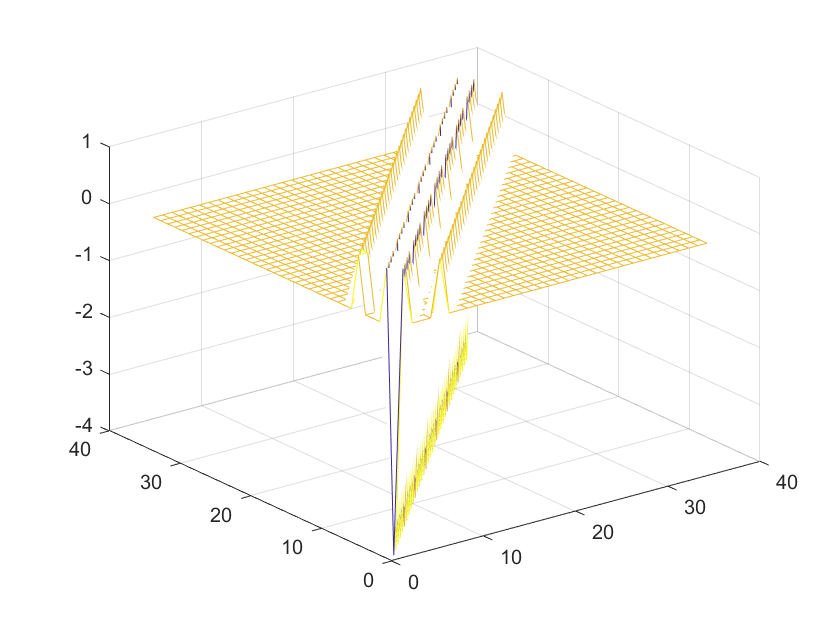


P(6,5)=0;
P(5,6)=0;
P(11,10)=0;
P(10,11)=0; 
P(16,15)=0; 
P(15,16)=0; 
P(21,20)=0; 
P(20,21)=0; 
P(26,25)=0; 
P(25,26)=0;
P(31,30)=0;
P(30,31)=0;
mesh(P)

## Création de la fonction: il s'agit de la fonction représentant le laplacien en chaque point



for y =[1:1:9]
    for x=[1:1:7]
        
            F(x,y)= 0*x^2 -0*y^2;

    end
end


## Valeurs de la température au contour du stade de foot


U11=37; 
U21=37;
U31=37;
U41=37;
U51=37;
U61=37;
U71=37;
U12=37;
U13=37;
U14=37;
U15=37;
U16=37;
U17=37;
U18=37;
U19=37;
U29=37;
U39=37;
U49=37;
U59=37;
U69=37;
U72=37;
U73=37;
U74=37;
U75=37;
U76=37;
U77=37;
U78=37;
U79=37;

%% Ecriture de la matrice représentant le second terme de notre équation : T

h=15^2; % h étant le pas entre deux points

T=[F(2,2)*h-U12-U21
    F(3,2)*h-U31
    F(4,2)*h-U41
    F(5,2)*h-U51
    F(6,2)*h-U61-U72
    F(2,3)*h-U13
    F(3,3)*h
    F(4,3)*h
    F(5,3)*h
    F(6,3)*h-U73
    F(2,4)*h-U14
    F(3,4)*h
    F(4,4)*h
    F(5,4)*h
    F(6,4)*h-U74
    F(2,5)*h-U15
    F(3,5)*h
    F(4,5)*h
    F(5,5)*h
    F(6,5)*h-U75
    F(2,6)*h-U16
    F(3,6)*h
    F(4,6)*h
    F(5,6)*h
    F(6,6)*h-U76
    F(2,7)*h-U17
    F(3,7)*h
    F(4,7)*h
    F(5,7)*h
    F(6,7)*h-U77 
    F(2,8)*h-U18-U29 
    F(3,8)*h-U39
    F(4,8)*h-U49
    F(5,8)*h-U59
    F(6,8)*h-U69-U78 ]

T =    -74
   -37
   -37
   -37
   -74
   -37
     0
     0
     0
   -37


    
%% Détermination des inconnues ( U22 U32 U42 U52 U62 U23 U33 U43 U53 U63 U24 U34 U44 U54 U64 U25 U35 U45 U55 U65 U26 U36 U46 U56 U66 U27 U37 U47 U57 U67 U28 U38 U48 U58 U68) ici, U22=A(1,1); U32=A(2,1) ainsi de suite jusqu'à U68= A(35,1)

A=P\T % nous stockons leur valeur dans une matrice A

A =    41.1443
   39.8983
   38.6446
   37.8567
   37.3648
   50.6790
   42.8042
   39.8232
   38.4176
   37.6025



%% Ecriture de la matrice finale

Z=zeros(7,9);
Z(1,1:9)=37;
Z(7,1:9)=37;
Z(1:7,1)=37;
Z(1:7,9)=37;
Z(2,2:8)=A(1:7);
Z(3,2:8)=A(8:14);
Z(4,2:8)=A(15:21);
Z(5,2:8)=A(22:28);
Z(6,2:8)=A(29:35);



% il s'agit de la matrice renfermant les coordonnées de l'ensemble des 63
% points présents sur la pelouse de notre stade
    

## tracer de la repartition de la chaleur

Z

Z =    37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000
   37.0000   41.1443   39.8983   38.6446   37.8567   37.3648   50.6790   42.8042   37.0000
   37.0000   39.8232   38.4176   37.6025   41.8693   40.8161   39.4266   38.3880   37.0000
   37.0000   37.6275   38.9822   39.1643   38.6792   38.0802   37.5196   37.8954   37.0000
   37.0000   38.1796   38.0458   37.7340   37.3708   37.4196   37.6128   37.5904   37.0000
   37.0000   37.4391   37.2295   37.1703   37.2617   37.2637   37.2027   37.1081   37.0000
   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000   37.0000


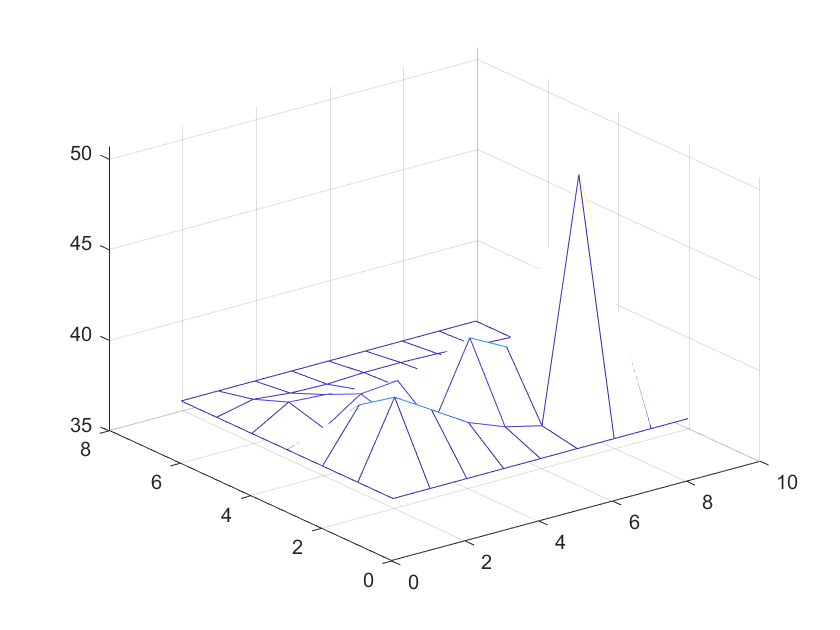

mesh (Z)